A6.6（`如何编写无参泛函中的目标函数`）实时脚本

由张志涌编写、修改于 2023.1。

1）`无参泛函与无参目标函数句柄配用`

k1=4;k2=10;     % k1,k2	是表述目标函数时所引入的变参
x12=[1.5,5];
C ='子集输入型匿名函数句柄fH=';
fH={@(x)k1*sin(tan(x))-k2*tan(sin(x-0.7)),...   %子集匿名句柄 <4>
    @(x)ZAobjFun(x,k1,k2)};                     %子集匿名句柄 <5>
Tfh={[C,char(fH{1})],[C,char(fH{2})]};
for ii=1:2
    disp('+++++++++++++++++++++++ ')
    disp(['正确配用方法 （',int2str(ii+3),')'])
    x0(ii)=ZAfzerotx(fH{ii},x12);  %无变参泛函ZAfzerotx调用格式	 <10>
    y0(ii)=fH{ii}(x0(ii));    
    disp('无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的')
    disp(['第一输入量是',Tfh{ii}])
    disp('所得搜索结果如下：')
    disp(['  零点位置为         ',num2str(x0(ii))])
    disp(['  该点处的函数值为   ',num2str(y0(ii))])
end

+++++++++++++++++++++++ 


正确配用方法 （4)


无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的


第一输入量是子集输入型匿名函数句柄fH=@(x)k1*sin(tan(x))-k2*tan(sin(x-0.7))


所得搜索结果如下：


  零点位置为         3.6372


  该点处的函数值为   3.1086e-15


+++++++++++++++++++++++ 


正确配用方法 （5)


无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的


第一输入量是子集输入型匿名函数句柄fH=@(x)ZAobjFun(x,k1,k2)


所得搜索结果如下：


  零点位置为         3.6372


  该点处的函数值为   3.1086e-15


2）图形

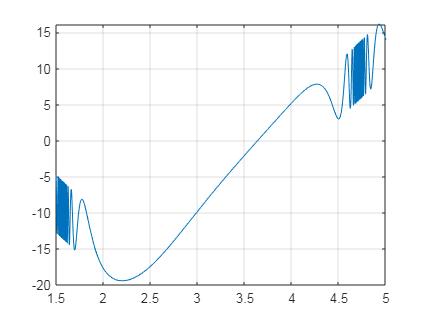

fplot(fH{1},x12)		%该绘图命令在此必须用单输入匿名函数句柄 <18>
grid on

set(gcf,'Color','white')
shg	

3）`含参泛函的无参格式与无参目标函数句柄配用`

for ii=1:2
    disp('+++++++++++++++++++++++ ')
    disp(['正确配用方法 （',int2str(ii+5),')'])
    x0(ii)=fzerotx(fH{ii},x12);  %含参泛函fzerotx的无参调用格式	 <25>
    y0(ii)=fH{ii}(x0(ii));    
    disp('含参泛函无参调用格式 fzerotx(fH,x12) 中，表述目标函数的')
    disp(['第一输入量是',Tfh{ii}])
    disp('所得搜索结果如下：')
    disp(['  零点位置为         ',num2str(x0(ii))])
    disp(['  该点处的函数值为   ',num2str(y0(ii))])
end

+++++++++++++++++++++++ 


正确配用方法 （6)


含参泛函无参调用格式 fzerotx(fH,x12) 中，表述目标函数的


第一输入量是子集输入型匿名函数句柄fH=@(x)k1*sin(tan(x))-k2*tan(sin(x-0.7))


所得搜索结果如下：


  零点位置为         3.6372


  该点处的函数值为   3.1086e-15


+++++++++++++++++++++++ 


正确配用方法 （7)


含参泛函无参调用格式 fzerotx(fH,x12) 中，表述目标函数的


第一输入量是子集输入型匿名函数句柄fH=@(x)ZAobjFun(x,k1,k2)


所得搜索结果如下：


  零点位置为         3.6372


  该点处的函数值为   3.1086e-15
